% --- MATLAB Script for System Identification and Analysis ---
% This script identifies the position transfer function, derives velocity
% and acceleration transfer functions, and then performs analysis including
% extracting natural frequencies, max velocity, and max acceleration.

clear; % Clear workspace variables
clc;   % Clear command window
close all; % Close all existing figure windows

% --- 1. Define the Original Given Data (User Updated) ---
disp('--- 1. Defining Original Data ---');

--- 1. Defining Original Data ---


original_plot_4_time = 0:0.01:0.12; % Time vector for the experiment
plot_4_step_constant = 14.5;       % Magnitude of the step input

% User updated response and velocity data (ensure column vectors)
original_plot_4_response = [0, 2, 3, 6, 12.5, 16, 17.8, 17, 15.4, 15, 15, 15, 15]'; % degrees
original_plot_4_velocity = [0, 25, 225, 500, 475, 220, 0, -65, -55, -10, 0, 0, 0]'; % deg/s

disp('Original time vector length:'); disp(length(original_plot_4_time));

Original time vector length:
    13



disp('Original response data:'); disp(original_plot_4_response');

Original response data:
         0    2.0000    3.0000    6.0000   12.5000   16.0000   17.8000   17.0000   15.4000   15.0000   15.0000   15.0000   15.0000



disp('Original velocity data:'); disp(original_plot_4_velocity');

Original velocity data:
     0    25   225   500   475   220     0   -65   -55   -10     0     0     0




% --- 2. Prepend Equilibrium Data ---
disp(newline);
disp('--- 2. Prepending Equilibrium Data ---');

--- 2. Prepending Equilibrium Data ---



Ts = original_plot_4_time(2) - original_plot_4_time(1);
nx = 5;

initial_response_equilibrium = original_plot_4_response(1);
initial_velocity_equilibrium = original_plot_4_velocity(1);
input_before_step = 0;

prepended_time_segment = ( (1:nx)' - nx - 1 ) * Ts + original_plot_4_time(1);

plot_4_time_prepended = [prepended_time_segment; original_plot_4_time'];
plot_4_response_prepended = [repmat(initial_response_equilibrium, nx, 1); original_plot_4_response];
plot_4_velocity_prepended = [repmat(initial_velocity_equilibrium, nx, 1); original_plot_4_velocity];

original_step_values = ones(length(original_plot_4_time), 1) * plot_4_step_constant;
step_array_prepended = [repmat(input_before_step, nx, 1); original_step_values];

disp(['Prepending ', num2str(nx), ' data points.']);

Prepending 5 data points.


disp('New total data length:'); disp(length(plot_4_time_prepended));

New total data length:
    18




% --- 3. Create iddata Object for Position ONLY ---
disp(newline);
disp('--- 3. Creating iddata Object for Position Estimation ---');

--- 3. Creating iddata Object for Position Estimation ---


data_for_position_estimation = iddata(plot_4_response_prepended, step_array_prepended, Ts);

data_for_position_estimation.InputName = {'StepInput'};
data_for_position_estimation.InputUnit = {'Unit_of_Input'};
data_for_position_estimation.OutputName = {'Position (deg)'};
data_for_position_estimation.OutputUnit = {'degrees'};
data_for_position_estimation.TimeUnit = 'seconds';

disp('iddata object summary (for position):');

iddata object summary (for position):


disp(data_for_position_estimation);

       iddata object: 18-by-1-by-1




% --- 4. Estimate Position Transfer Function (G_pos) ---
disp(newline);
disp('--- 4. Estimating Position Transfer Function (G_pos(s)) ---');

--- 4. Estimating Position Transfer Function (G_pos(s)) ---



num_poles_pos = 3;
num_zeros_pos = 0;

disp(['Estimating G_pos(s) with num_poles = ', num2str(num_poles_pos), ', num_zeros = ', num2str(num_zeros_pos)]);

Estimating G_pos(s) with num_poles = 3, num_zeros = 0


G_pos_estimated = [];
try
    G_pos_estimated = tfest(data_for_position_estimation, num_poles_pos, num_zeros_pos);
    disp('G_pos(s) estimation process completed.');
catch ME
    disp('ERROR during G_pos(s) estimation:');
    disp(ME.message);
    disp('Exiting script due to estimation error.');
    return;
end

G_pos(s) estimation process completed.



% --- 5. Derive Velocity & Acceleration TFs and Display ---
G_vel_derived = []; % Initialize for scope
G_acc_derived = []; % Initialize for scope
if ~isempty(G_pos_estimated)
    disp(newline);
    disp('--- 5. Deriving Velocity & Acceleration TFs and Displaying ---');
    
    s = tf('s');
    G_vel_derived = s * G_pos_estimated;
    G_vel_derived = minreal(G_vel_derived);

    G_acc_derived = s * G_vel_derived; % Or s^2 * G_pos_estimated
    G_acc_derived = minreal(G_acc_derived);

    disp("Estimated Position Transfer Function: G_pos(s)");
    tf(G_pos_estimated)

    disp(newline);
    disp("Derived Velocity Transfer Function: G_vel_derived(s) = s * G_pos(s)");
    tf(G_vel_derived)
    
    disp(newline);
    disp("Derived Acceleration Transfer Function: G_acc_derived(s) = s * G_vel_derived(s)");
    tf(G_acc_derived)

    % Coefficients display can be added here if needed
else
    disp('Skipping TF display as G_pos(s) estimation failed.');
end

--- 5. Deriving Velocity & Acceleration TFs and Displaying ---


Estimated Position Transfer Function: G_pos(s)



ans =
 
  From input "StepInput" to output "Position (deg)":
               2.385e05
  ----------------------------------
  s^3 + 69.29 s^2 + 6992 s + 2.13e05
 
Continuous-time transfer function.
Model Properties


Derived Velocity Transfer Function: G_vel_derived(s) = s * G_pos(s)



ans =
 
  From input "StepInput" to output:
              2.385e05 s
  ----------------------------------
  s^3 + 69.29 s^2 + 6992 s + 2.13e05
 
Continuous-time transfer function.
Model Properties


Derived Acceleration Transfer Function: G_acc_derived(s) = s * G_vel_derived(s)



ans =
 
  From input "StepInput" to output:
             2.385e05 s^2
  ----------------------------------
  s^3 + 69.29 s^2 + 6992 s + 2.13e05
 
Continuous-time transfer function.
Model Properties



% --- 6. Simulate Time Responses ---
simulated_position = [];
simulated_velocity = [];
simulated_acceleration = [];
if ~isempty(G_pos_estimated) && ~isempty(G_vel_derived) && ~isempty(G_acc_derived)
    disp(newline);
    disp('--- 6. Simulating Time Responses ---');
    simulated_position = lsim(G_pos_estimated, step_array_prepended, plot_4_time_prepended);
    simulated_velocity = lsim(G_vel_derived, step_array_prepended, plot_4_time_prepended);
    simulated_acceleration = lsim(G_acc_derived, step_array_prepended, plot_4_time_prepended);
    disp('Time response simulations completed.');
else
    disp('Skipping time response simulations as a required TF is missing.');
end

--- 6. Simulating Time Responses ---


Time response simulations completed.


--- 7. Comparing Model Responses with Measured Data ---


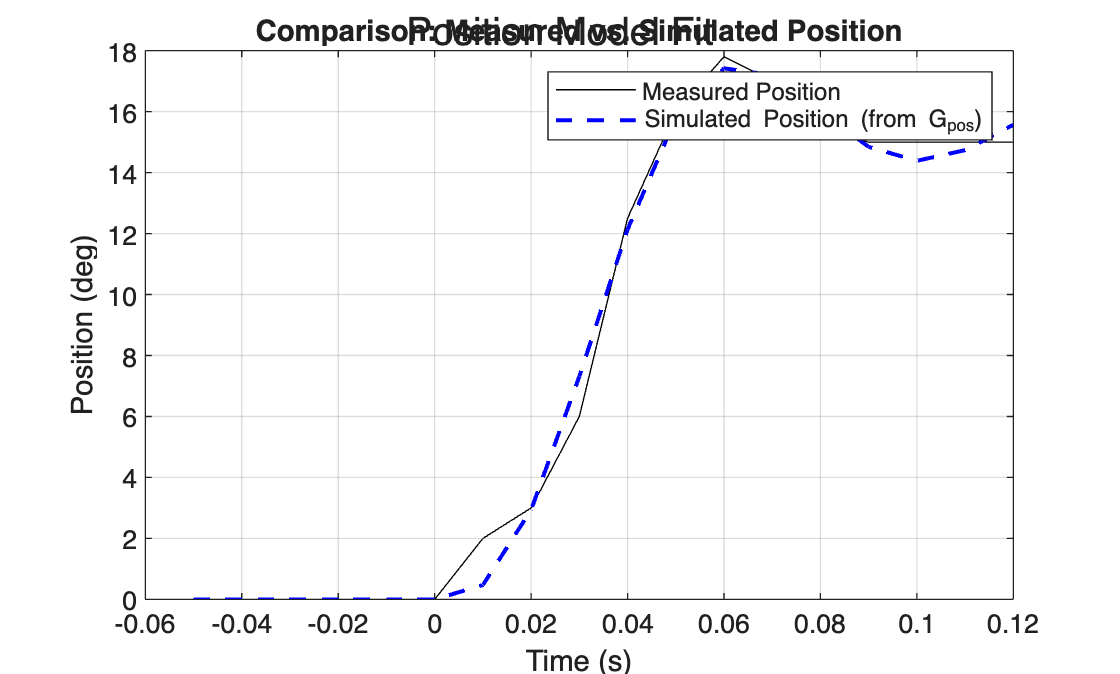

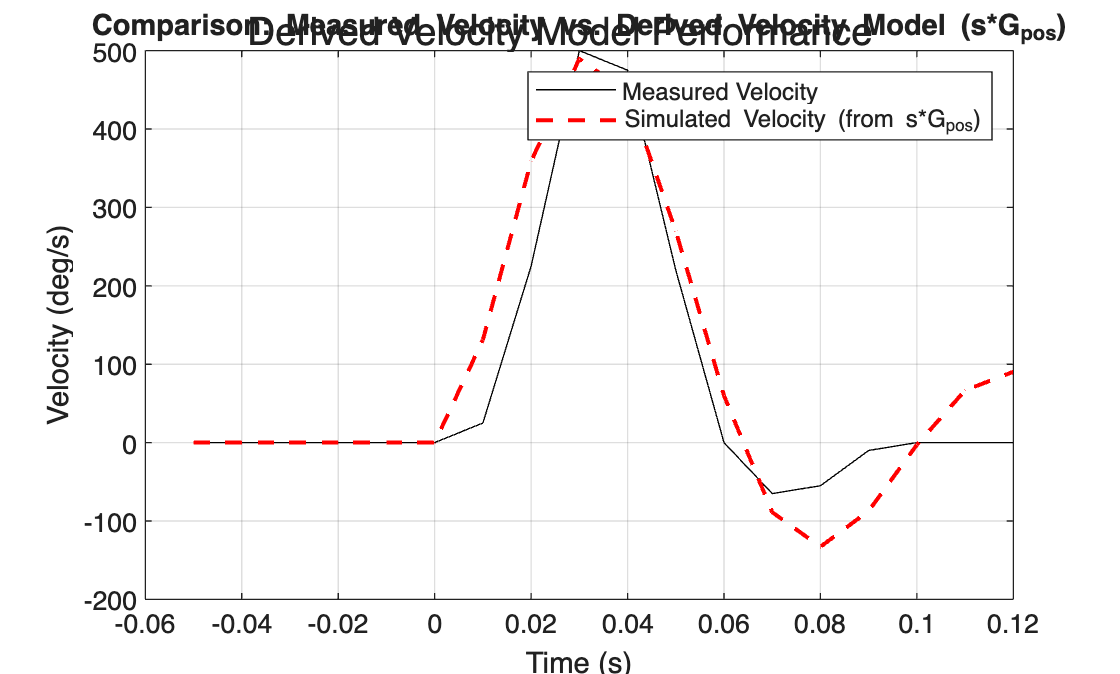

Approximate fit of derived velocity model to measured velocity: 64.49%


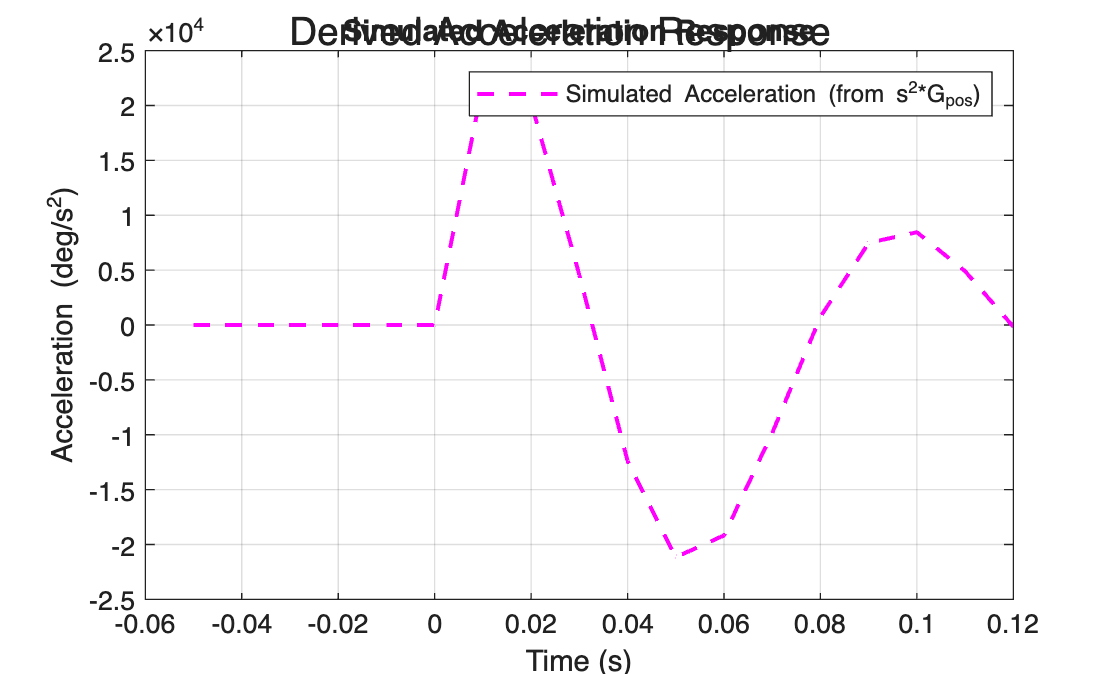


% --- 7. Compare Model Responses with Measured Data ---
if ~isempty(simulated_position)
    disp(newline);
    disp('--- 7. Comparing Model Responses with Measured Data ---');

    figure; % Position
    plot(plot_4_time_prepended, plot_4_response_prepended, 'k', 'DisplayName', 'Measured Position');
    hold on;
    plot(plot_4_time_prepended, simulated_position, 'b--', 'LineWidth', 1.5, 'DisplayName', 'Simulated Position (from G_{pos})');
    hold off;
    xlabel('Time (s)'); ylabel('Position (deg)');
    title('Comparison: Measured vs. Simulated Position');
    legend('show'); grid on; sgtitle('Position Model Fit');

    if ~isempty(simulated_velocity)
        figure; % Velocity
        plot(plot_4_time_prepended, plot_4_velocity_prepended, 'k', 'DisplayName', 'Measured Velocity');
        hold on;
        plot(plot_4_time_prepended, simulated_velocity, 'r--', 'LineWidth', 1.5, 'DisplayName', 'Simulated Velocity (from s*G_{pos})');
        hold off;
        xlabel('Time (s)'); ylabel('Velocity (deg/s)');
        title('Comparison: Measured Velocity vs. Derived Velocity Model (s*G_{pos})');
        legend('show'); grid on; sgtitle('Derived Velocity Model Performance');
        
        valid_indices_vel = ~isnan(simulated_velocity) & ~isnan(plot_4_velocity_prepended);
        if any(valid_indices_vel)
          fit_percentage_velocity = 100 * (1 - norm(plot_4_velocity_prepended(valid_indices_vel) - simulated_velocity(valid_indices_vel)) / norm(plot_4_velocity_prepended(valid_indices_vel) - mean(plot_4_velocity_prepended(valid_indices_vel))));
          disp(newline);
          disp(['Approximate fit of derived velocity model to measured velocity: ', num2str(fit_percentage_velocity, '%.2f'), '%']);
        end
    end
    
    if ~isempty(simulated_acceleration) % Optional: Plot acceleration
        figure; % Acceleration
        plot(plot_4_time_prepended, simulated_acceleration, 'm--', 'LineWidth', 1.5, 'DisplayName', 'Simulated Acceleration (from s^2*G_{pos})');
        xlabel('Time (s)'); ylabel('Acceleration (deg/s^2)');
        title('Simulated Acceleration Response');
        legend('show'); grid on; sgtitle('Derived Acceleration Response');
    end
else
    disp('Skipping response comparison due to missing simulated data.');
end

--- 8. Generating Bode Plots ---


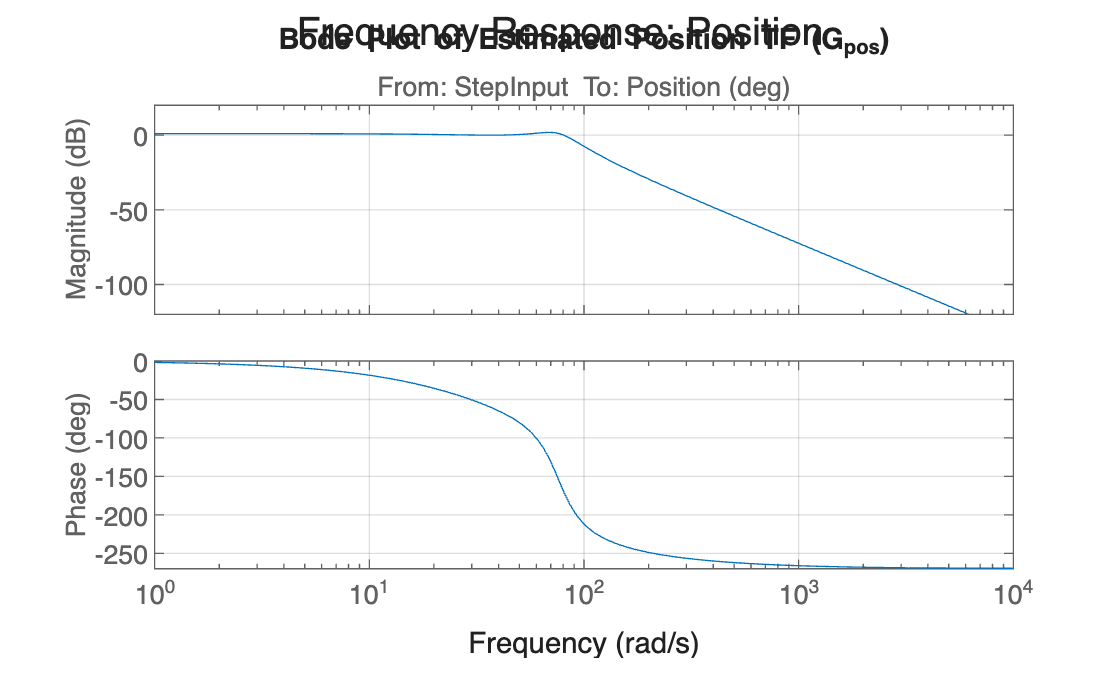

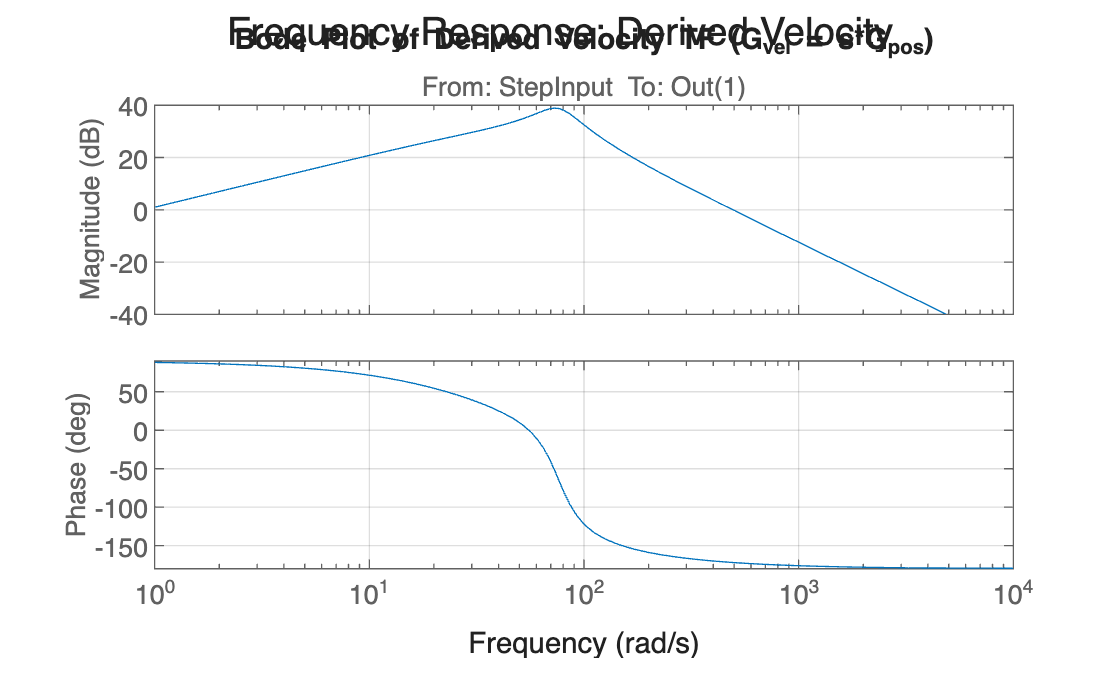

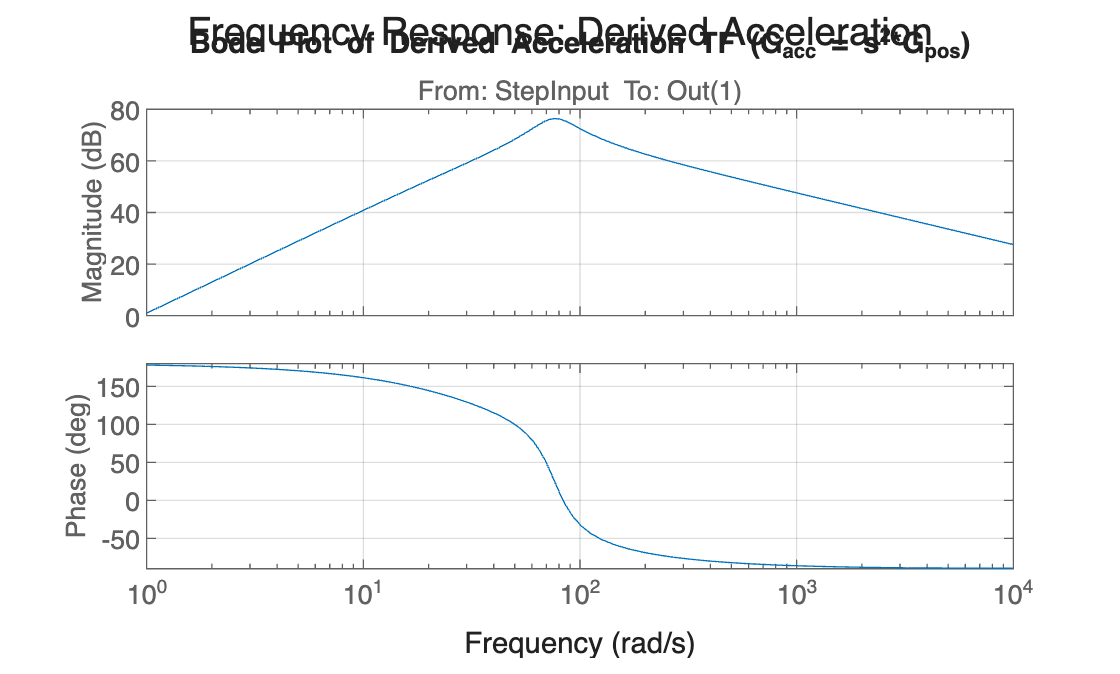


% --- 8. Generate and Display Bode Plots ---
if ~isempty(G_pos_estimated) && ~isempty(G_vel_derived) && ~isempty(G_acc_derived)
    disp(newline);
    disp('--- 8. Generating Bode Plots ---');

    figure; bode(G_pos_estimated); grid on;
    title('Bode Plot of Estimated Position TF (G_{pos})'); sgtitle('Frequency Response: Position');

    figure; bode(G_vel_derived); grid on;
    title('Bode Plot of Derived Velocity TF (G_{vel} = s*G_{pos})'); sgtitle('Frequency Response: Derived Velocity');
    
    figure; bode(G_acc_derived); grid on;
    title('Bode Plot of Derived Acceleration TF (G_{acc} = s^2*G_{pos})'); sgtitle('Frequency Response: Derived Acceleration');
else
    disp('Skipping Bode plots as a required TF is missing.');
end


% --- 9. Extract and Display Natural Frequencies and Damping Ratios ---
if ~isempty(G_pos_estimated)
    disp(newline);
    disp('--- 9. Analyzing Poles of G_pos_estimated ---');
    
    poles_pos = pole(G_pos_estimated);
    disp('Poles of G_pos_estimated:'); disp(poles_pos);
    
    natural_frequencies_rad_s = []; damping_ratios = [];
    for i = 1:length(poles_pos)
        p = poles_pos(i); wn_val = abs(p);
        natural_frequencies_rad_s = [natural_frequencies_rad_s; wn_val];
        if wn_val > 1e-6, zeta_val = -real(p) / wn_val; else zeta_val = NaN; end
        damping_ratios = [damping_ratios; zeta_val];
    end
    disp('Calculated Natural Frequencies (rad/s) (magnitude of poles):'); disp(natural_frequencies_rad_s);
    disp('Calculated Damping Ratios (-real(pole)/abs(pole)):'); disp(damping_ratios);

    complex_poles_freqs = abs(poles_pos(imag(poles_pos) ~= 0));
    if ~isempty(complex_poles_freqs)
        dominant_natural_freq_rad_s = max(unique(complex_poles_freqs)); 
        disp(newline);
        disp(['Dominant Natural Frequency from complex poles: ', num2str(dominant_natural_freq_rad_s), ' rad/s (', num2str(dominant_natural_freq_rad_s / (2*pi)), ' Hz)']);
    elseif ~isempty(poles_pos)
        dominant_natural_freq_rad_s = max(abs(poles_pos));
        disp(newline);
        disp(['System has only real poles. Max pole magnitude: ', num2str(dominant_natural_freq_rad_s), ' rad/s']);
    else
        disp(newline); disp('No poles found.');
    end
else
    disp('Skipping pole analysis as G_pos(s) estimation failed.');
end

--- 9. Analyzing Poles of G_pos_estimated ---


Poles of G_pos_estimated:
 -16.2765 +74.3735i
 -16.2765 -74.3735i
 -36.7389 + 0.0000i



Calculated Natural Frequencies (rad/s) (magnitude of poles):
   76.1338
   76.1338
   36.7389



Calculated Damping Ratios (-real(pole)/abs(pole)):
    0.2138
    0.2138
    1.0000



Dominant Natural Frequency from complex poles: 76.1338 rad/s (12.1171 Hz)



% --- 10. Extract and Display Max Angular Velocity and Acceleration ---
if ~isempty(simulated_velocity) && ~isempty(simulated_acceleration)
    disp(newline);
    disp('--- 10. Maximum Simulated Angular Velocity and Acceleration ---');
    
    max_angular_velocity = max(simulated_velocity);
    max_angular_acceleration = max(simulated_acceleration);
    
    disp(['Maximum Simulated Angular Velocity: ', num2str(max_angular_velocity), ' deg/s']);
    disp(['Maximum Simulated Angular Acceleration: ', num2str(max_angular_acceleration), ' deg/s^2']);
    
    % Find time of occurrence (optional)
    time_max_vel = plot_4_time_prepended(simulated_velocity == max_angular_velocity);
    time_max_acc = plot_4_time_prepended(simulated_acceleration == max_angular_acceleration);
    
    if ~isempty(time_max_vel)
        disp(['   Occurs at time(s): ', num2str(time_max_vel(1)), ' s (first occurrence)']);
    end
    if ~isempty(time_max_acc)
        disp(['   Occurs at time(s): ', num2str(time_max_acc(1)), ' s (first occurrence)']);
    end
else
    disp(newline);
    disp('Could not calculate max velocity/acceleration as simulations were not run or failed.');
end

--- 10. Maximum Simulated Angular Velocity and Acceleration ---


Maximum Simulated Angular Velocity: 489.3908 deg/s


Maximum Simulated Angular Acceleration: 21941.1193 deg/s^2


   Occurs at time(s): 0.03 s (first occurrence)


   Occurs at time(s): 0.01 s (first occurrence)



disp(newline);
disp('--- Script Finished ---');

--- Script Finished ---
